clear all;
close all;

z_length=10*1000; % z length
x_length=20*1000; % bus length
y_length=1*1000; % lattice k length

division=[100 100 100];% division along x,y,z
x_list=(0:(x_length/division(1)):x_length)-x_length/2;
y_list=(0:(y_length/division(2)):y_length)-y_length/2;
z_list=(0:(z_length/division(3)):z_length)-z_length;


x=0;y=0;z_range=100:100:5000;


bx_sum=zeros(length(z_range),1);
by_sum=zeros(length(z_range),1);
bz_sum=zeros(length(z_range),1);

mx=0;my=0;mz=1;
for z_index=1:length(z_range)
    z=z_range(z_index)
    for i=1:division(1)-1
        x0=x_list(i);
        for j=1:division(2)-1
            y0=y_list(j);
            for k=1:division(3)-1
                z0=z_list(k);
                [bx,by,bz]=magnet(x,y,z,x0,y0,z0,mx,my,mz);
                bx_sum(z_index)=bx+bx_sum(z_index);
                by_sum(z_index)=by+by_sum(z_index);
                bz_sum(z_index)=bz+bz_sum(z_index);
            end
        end
    end
end

z = 100

z = 200

z = 300

z = 400

z = 500

z = 600

z = 700

z = 800

z = 900

z = 1000

z = 1100

z = 1200

z = 1300

z = 1400

z = 1500

z = 1600

z = 1700

z = 1800

z = 1900

z = 2000

z = 2100

z = 2200

z = 2300

z = 2400

z = 2500

z = 2600

z = 2700

z = 2800

z = 2900

z = 3000

z = 3100

z = 3200

z = 3300

z = 3400

z = 3500

z = 3600

z = 3700

z = 3800

z = 3900

z = 4000

z = 4100

z = 4200

z = 4300

z = 4400

z = 4500

z = 4600

z = 4700

z = 4800

z = 4900

z = 5000

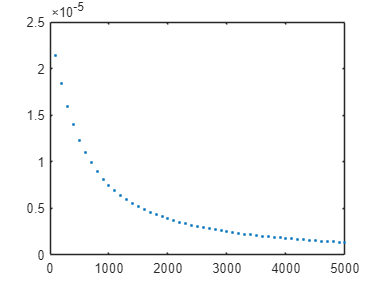

plot(z_range,bz_sum,'.'); hold on;

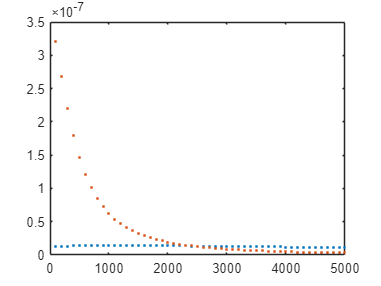

figure;
plot(z_range,bx_sum,'.');hold on;
plot(z_range,by_sum,'.');

function [bx,by,bz]=magnet(x,y,z,x0,y0,z0,mx,my,mz) % sensor xyz;
    distance=sqrt((x-x0)^2+(y-y0)^2+(z-z0)^2);
    m_dot_r=(mx*(x-x0)+my*(y-y0)+mz*(z-z0))/distance;
    bx=(3*m_dot_r*(x-x0)/distance-mx)/distance^3;
    by=(3*m_dot_r*(y-y0)/distance-my)/distance^3;
    bz=(3*m_dot_r*(z-z0)/distance-mz)/distance^3;
end

